Reto 1: Parte 2

Profundización II: Electromedicina

Restauración de imágenes de leucocitos de un canino.

Leandro Ramos - 219160001

Brandon Rosero - 219160289

Inicio del código

clear; close all; clc

Obtención de la imágen

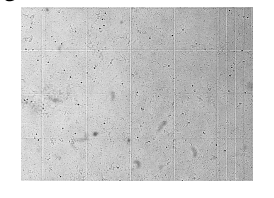

I=imread("S2_1.bmp");
I=I(:,:,1);
imshow(I,[])
title('Imagen obtenida del microscopio','fontsize',14,'interpreter','latex');

Transformada de Fourier

If=(fft2(I));
If1=real(fftshift(If));
imshow(log(1+(If1)),[])

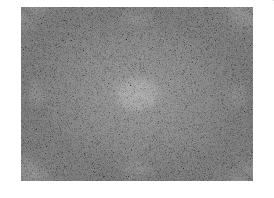

title('Espectro de Fourier de la imagen','fontsize',14,'interpreter','latex')

Creación del filtro Notch

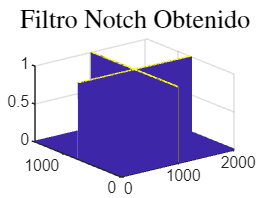

[P , Q]=size(If); %p filas q columbas
D=zeros(P,Q); %crear la matriz del mismo tamaño que la imágen
Do=1; %humbral de frecuencia
p2 = round(P/2);
q2 = round(Q/2);
D([p2-Do p2+Do],1:end) = 1 ;
D(1:end,[q2-Do q2+Do]) = 1;
H = D;
% mesh(H)
title("Filtro Notch Obtenido",'fontsize',14,'interpreter','latex')

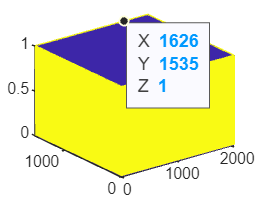


H1=fftshift(H);
mesh(H1)

title('Filtro Notch Obtenido Con fftshift','fontsize',14,'interpreter','latex')


Aplicación del filtro y eliminación de Interferencias

Bf=If.*H1;
%imshow(log(1+abs(Bf)),[])
I2=(ifft2(Bf)); 

Ift=double(I)-I2;

imshow(I2,[])

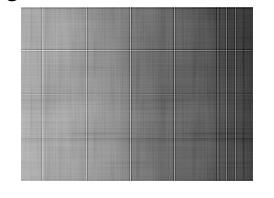

title("Imagen de interferencia obtenida",'fontsize',14,'interpreter','latex')

imshow(Ift,[]);

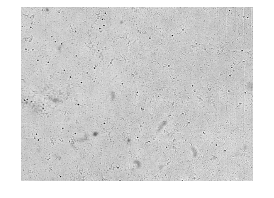

title("Imagen con la interferencia eliminada",'fontsize',14,'interpreter','latex')

Filtro WIener

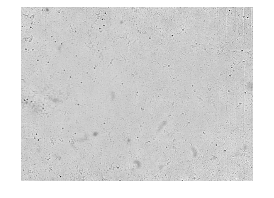

imagenfiltrada = wiener2(Ift, [1000 1000]);
Iop=Ift-imagenfiltrada;
imshow(Iop,[]);

Fondo de imágen

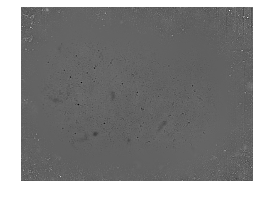

Wa=(imcomplement(double(I).*Ift)-imcomplement(double(I)).*imcomplement(Ift))/(imcomplement(Ift.*Ift)-imcomplement(Ift).*imcomplement(Ift));

Iout=Ift-Iop;
imshow(Iout,[]);